# **Sygnals and Systems - Dr. Akhavan**

## CA5 - Matin Bazrafshan

# Part 0

if we consider a signal with $f_s =20\;\textrm{Hz}$ ,$T=1\;s$ and $N=100$ the frequency resolution will be $\delta_s =\frac{f_s }{N}=1$ , so we can not detect picks with distance less than 1.

for example signal $x_1 \left(t\right)=e^{2\pi j\left(5t\right)} +e^{2\pi j\left(8t\right)}$ have the picks on 5 and 8 respectively as the fourier transform of it is $\mathcal{F}\left(e^{2\pi j\left(5t\right)} +e^{2\pi j\left(8t\right)} \right)=\delta \left(\omega -5\right)+\delta \left(\omega -8\right)\;\ldotp$ the distance between two pulse is 3 so it will be shown well.

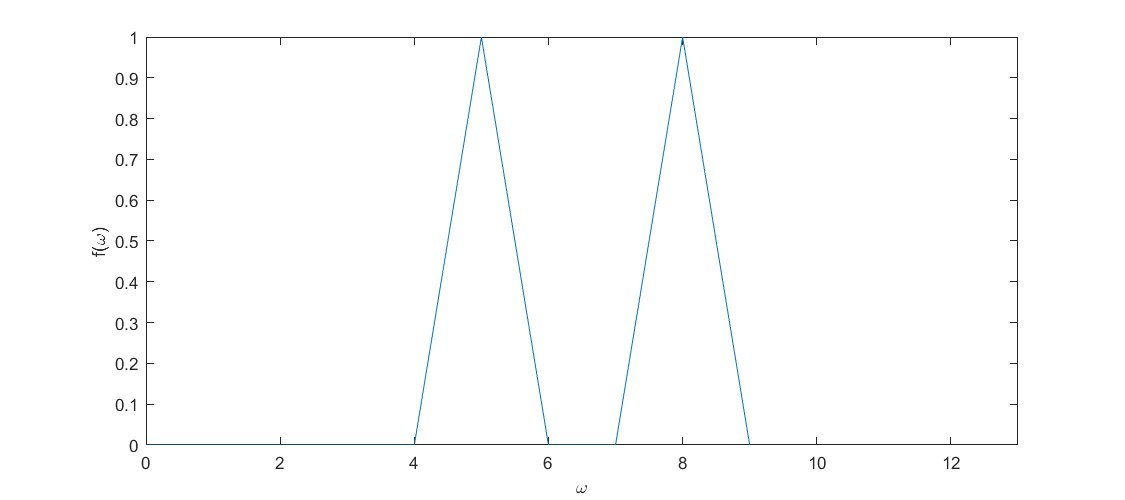

clearvars;
fs = 20;
ts = 1 / fs;
tstart = 0;
tend = 1;
t = tstart : ts : tend - ts;
T = tend - tstart;
N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;


x1 = exp(1i * 2 * pi * 5 * t) + exp(1i * 2 * pi * 8 * t);
y1 = fftshift(fft(x1));
y1 = y1 / max(y1);

figure('Position', [0 0 900 400]);
plot(f,abs(y1));
xlim([0 13]);
xlabel('\omega');
ylabel('f(\omega)');

but in signal $x_2 \left(t\right)=e^{2\pi j\left(5t\right)} +e^{2\pi j\left(5\ldotp 1t\right)}$we have $\mathcal{F}\left(e^{2\pi j\left(5t\right)} +e^{2\pi j\left(8t\right)} \right)=\delta \left(\omega -5\right)+\delta \left(\omega -5\ldotp 1\right)\;$so the distance is 0.1 and can not be detected.

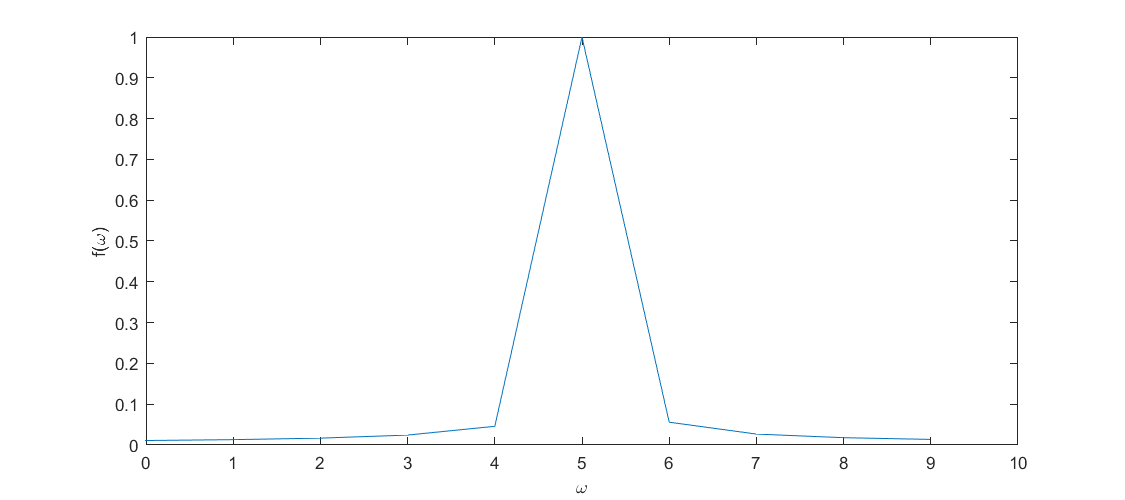

x2 = exp(1i * 2 * pi * 5 * t) + exp(1i * 2 * pi * 5.1 * t);
y2 = fftshift(fft(x2));
y2 = y2 / max(y2);

figure('Position', [0 0 900 400]);
plot(f,abs(y2));
xlim([0 10]);
xlabel('\omega');
ylabel('f(\omega)');

# Part 1

### 1.1

first we plot $x_1 \left(t\right)=\mathrm{cos}\left(10\pi t\right)$ with parameters:

- 
$$f_s =50$$


- 
$$t=\left(-1,1\right)$$


- 
$$T=2$$


- 
$$N=T\times \;f_s$$


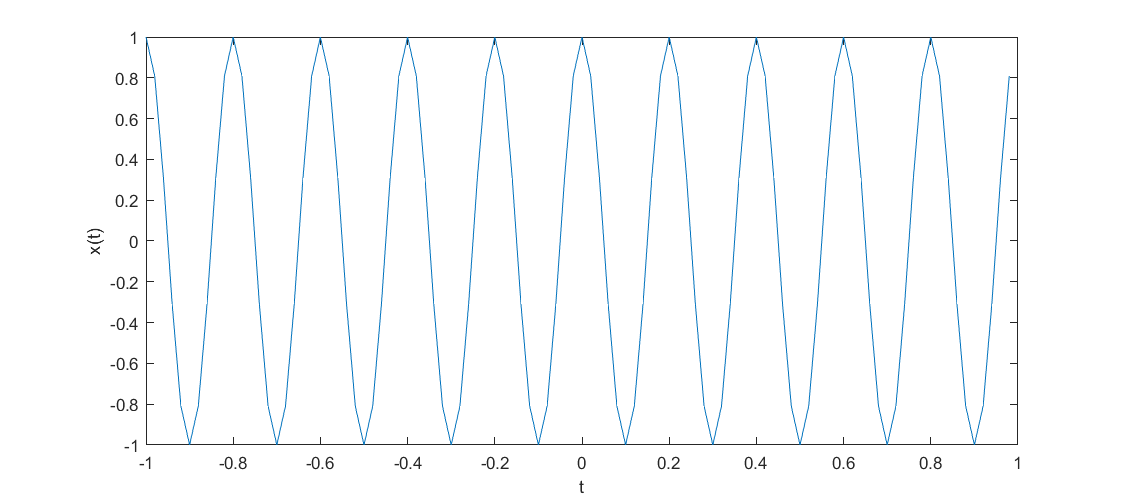

clearvars;
fs = 50;
ts = 1 / fs;
tstart = -1;
tend = 1;
t = tstart : ts : tend - ts;
T = tend - tstart;
N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;


figure('Position', [0 0 900 400]);
x1 = cos(10 * pi * t);
plot(t,x1);
xlabel('t');
ylabel('x(t)')

first we need to calculate the fourier transform:

- 
$$x_1 \left(t\right)=\cos \left(10\pi t\right)\;\to \mathcal{F}\left(x_1 \left(t\right)\right)=\pi \left(\delta \left(\omega -10\pi \right)+\delta \left(\omega +10\pi \right)\right)$$


after that we normalize the output by dividing it to the maximum absolute value of it:

-  
$${\hat{x} }_1 \left(\omega \right)=\frac{{\hat{x} }_1 \left(\omega \right)}{\max \left(\left|{\hat{x} }_1 \left(\omega \right)\right|\right)}$$


then we consider the $f=\frac{\omega }{2\pi }$ so:

- 
$${\hat{x} }_1 \left(f\right)=\delta \left(f-5\right)+\delta \left(f+5\right)$$


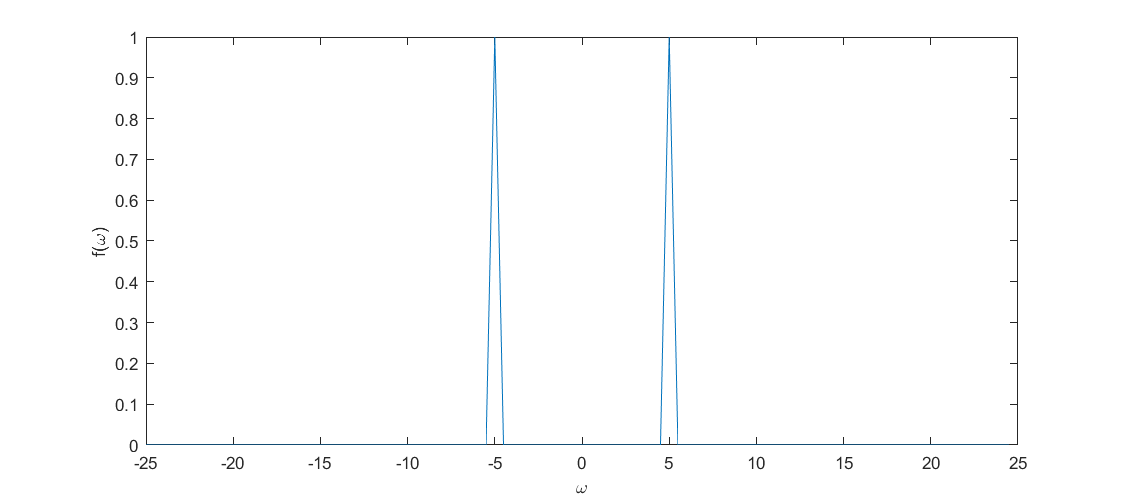

y1 = fftshift(fft(x1));
y1 = y1 / max(abs(y1));

figure('Position', [0 0 900 400]);
plot(f,abs(y1));
xlabel('\omega');
ylabel('f(\omega)')

### 1.2

first we plot $x_2 \left(t\right)=\cos \left(30\pi t+\frac{\pi }{4}\right)$ with parameters:

- 
$$f_s =100$$


- 
$$t=\left(0,1\right)$$


- 
$$T=1$$


- 
$$N=T\times \;f_s$$


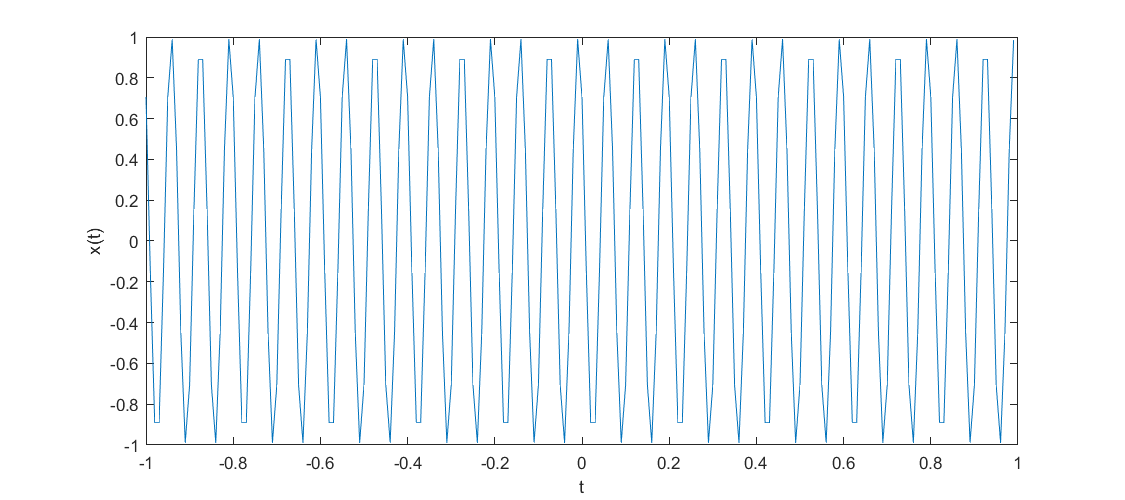

clearvars;
fs = 100;
ts = 1 / fs;
tstart = -1;
tend = 1;
t = tstart : ts : tend - ts;
T = tend - tstart;
N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;


figure('Position', [0 0 900 400]);
x2 = cos(30 * pi * t + pi / 4);
plot(t,x2);
xlabel('t');
ylabel('x(t)')

first we need to calculate the fourier transform:

- 
$$x_2 \left(t\right)=\mathrm{cos}\left(30\pi t+\frac{\pi }{4}\right)\;\to \mathcal{F}\left(x_1 \left(t\right)\right)=\pi \left(e^{j\frac{\pi }{4}\omega } \;\delta \left(\omega -30\pi \right)+e^{-j\frac{\pi }{4}\omega } \delta \left(\omega -30\pi \right)\right)$$


after that we normalize the output by dividing it to the maximum absolute value of it:

-  
$${\hat{x} }_2 \left(\omega \right)=\frac{{\hat{x} }_1 \left(\omega \right)}{\max \left(\left|{\hat{x} }_1 \left(\omega \right)\right|\right)}$$


then we consider the $f=\frac{\omega }{2\pi }$ so:

- 
$${\hat{x} }_2 \left(f\right)=e^{j\frac{\pi }{4}} \delta \left(f-15\right)+e^{-j\frac{\pi }{4}} \delta \left(f+15\right)$$


We expect two picks on $\pm 15$, as we plot ${\hat{\left|x\right.} }_2 \left(f\right)\left|\right.$ 

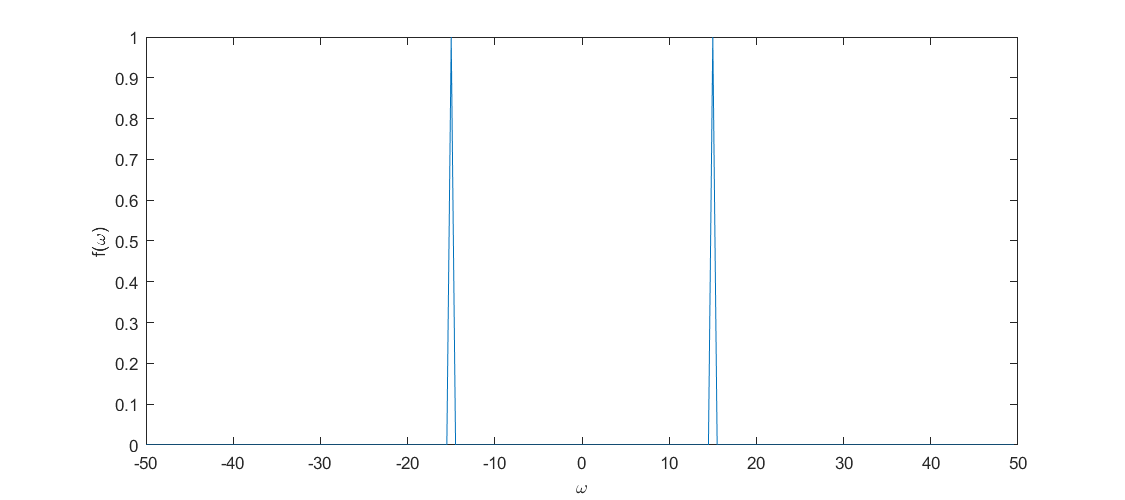

y2 = fftshift(fft(x2));
y2 = y2 / max(abs(y2));

figure('Position', [0 0 900 400]);
plot(f,abs(y2));
xlabel('\omega');
ylabel('f(\omega)')

And in plotting phase of ${\hat{x} }_2 \left(f\right)=e^{j\frac{\pi }{4}} \delta \left(f-15\right)+e^{-j\frac{\pi }{4}} \delta \left(f+15\right)$, we consider y-axis ticks is $\pi$, so there should be a $-\frac{1}{4}$ on $-15$ and a $\frac{1}{4}$ on $15$.

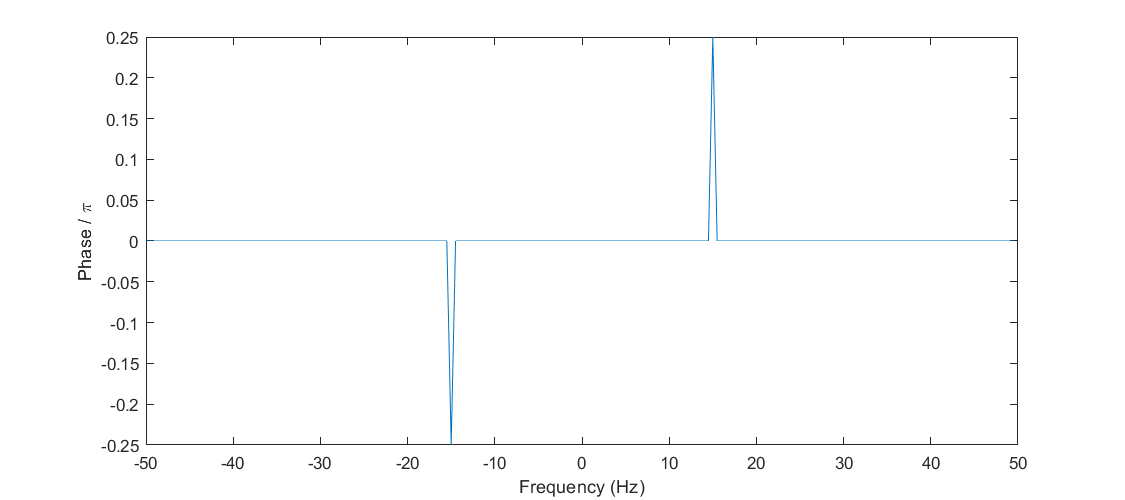

threshold = 1e-6;
y2(abs(y2) < threshold) = 0;
theta = angle(y2);
plot(f,theta/pi);
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

# Part 2

### 2.1 Creating Mapset

clearvars;
mapset = create_mapset()

mapset = 2×32 cell array
    {'a'    }    {'b'    }    {'c'    }    {'d'    }    {'e'    }    {'f'    }    {'g'    }    {'h'    }    {'i'    }    {'j'    }    {'k'    }    {'l'    }    {'m'    }    {'n'    }    {'o'    }    {'p'    }    {'q'    }    {'r'    }    {'s'    }    {'t'    }    {'u'    }    {'v'    }    {'w'    }    {'x'    }    {'y'    }    {'z'    }    {' '    }    {'.'    }    {','    }    {'!'    }    {'"'    }    {';'    }
    {'00000'}    {'00001'}    {'00010'}    {'00011'}    {'00100'}    {'00101'}    {'00110'}    {'00111'}    {'01000'}    {'01001'}    {'01010'}    {'01011'}    {'01100'}    {'01101'}    {'01110'}    {'01111'}    {'10000'}    {'10001'}    {'10010'}    {'10011'}    {'10100'}    {'10101'}    {'10110'}    {'10111'}    {'11000'}    {'11001'}    {'11010'}    {'11011'}    {'11100'}    {'11101'}    {'11110'}    {'11111'}


### 2.2 - 2.3 Encoding message

To encode message we need to find a proper$f$ to encode bitstrings. Consider $\mathrm{bitrate}=n$ so there is $2^n$ possibilites for our bitstrings. So we divide our valid frequency range by $2^n$. Valide range for frequency is $(0,\frac{f_s}{2}]$, because sine function has two symmetric pulses, there is no need to use negative frequencies. so each distance(we call them step) between two used frequencies is $f_{\mathrm{step}} =\frac{f_{\frac{s}{2}} }{2^n }$, and initial frequncy is $\frac{f_{\mathrm{step}} }{2}$. so $f=f_{\mathrm{init}} +i\times f_{\mathrm{step}}$where $i\in \left\lbrack 0,2^n -1\right\rbrack$.

*Another thing I consider is that if length of a message is not dividable by bitrate, I add as many as needed semicolons to fix that issue,so if you see semicolons at the end of decoded messages, it is not noise or miscoding.*

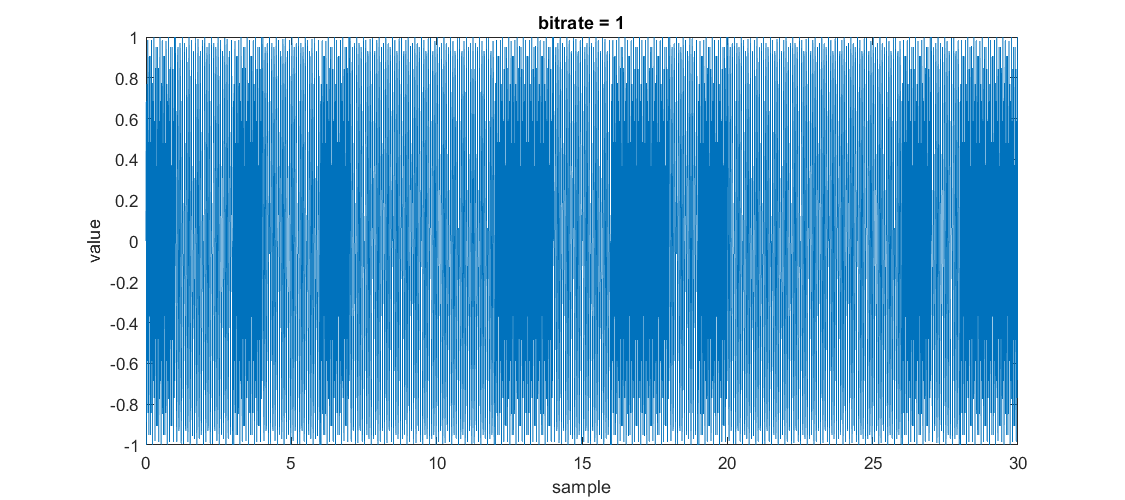

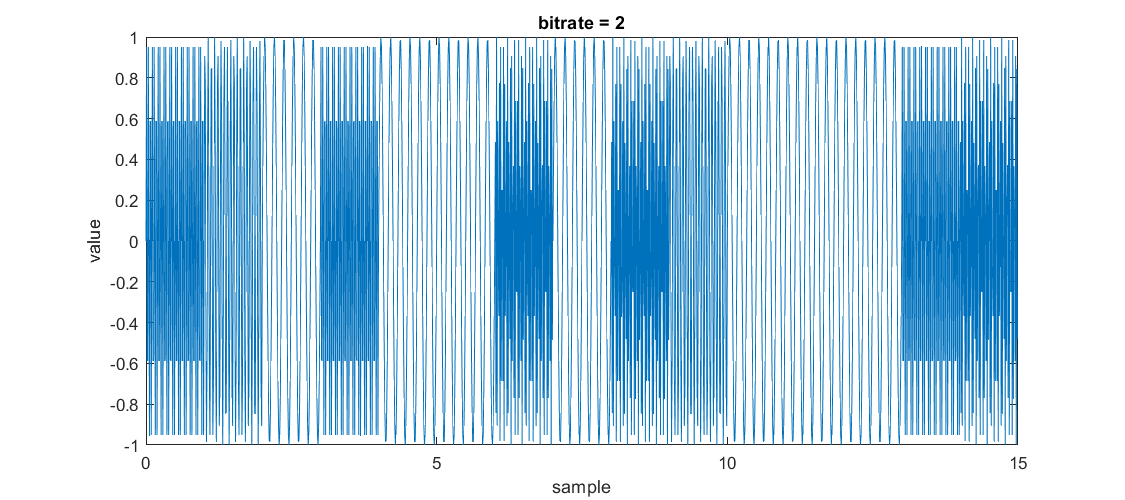

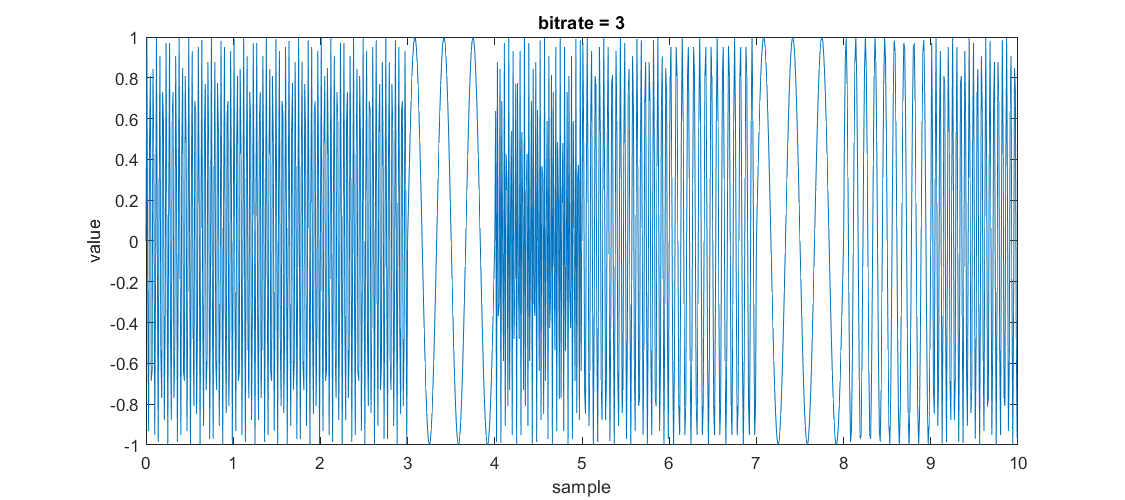

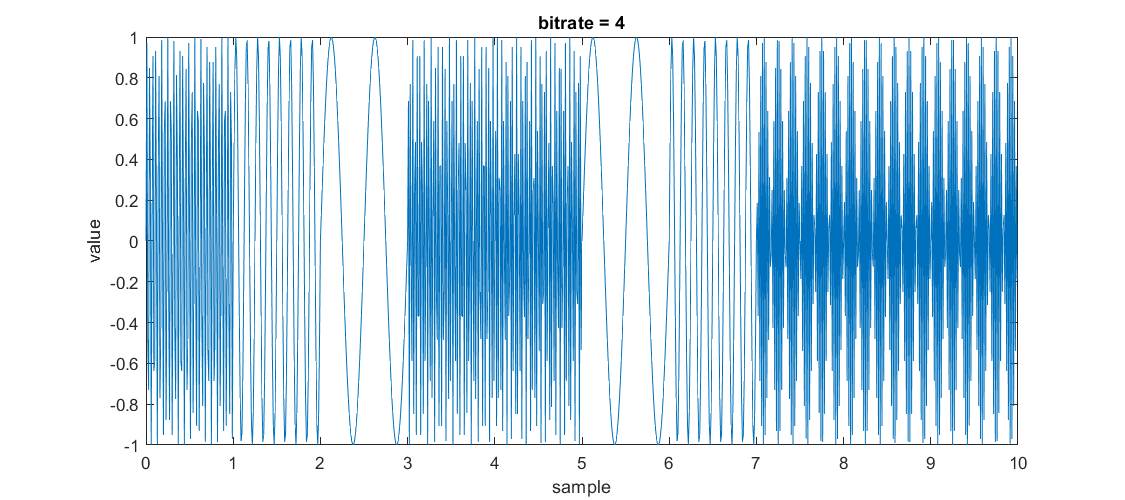

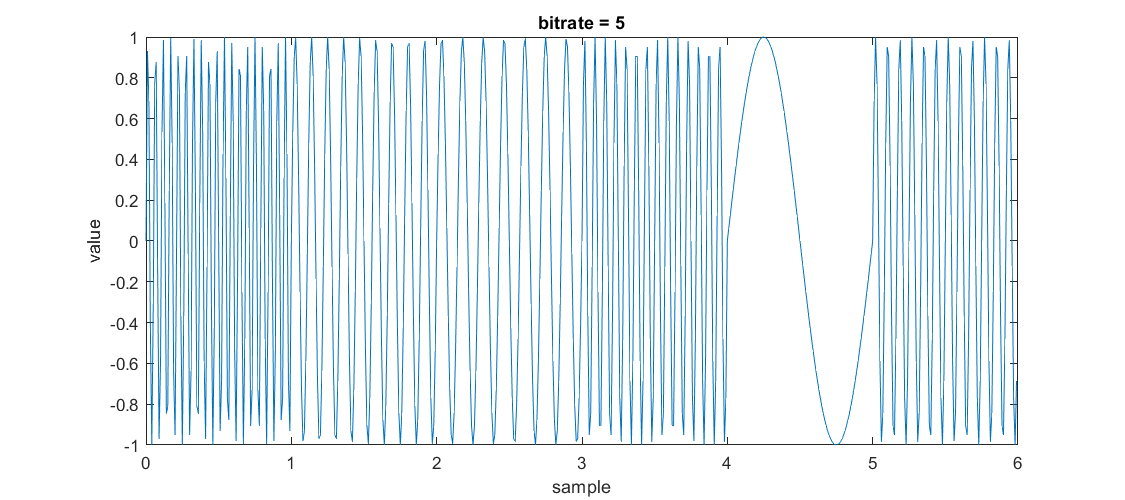

fs = 100;
ts = 1 / fs;

message = 'signal';

bit_rates = [1,2,3,4,5];
for i = 1:length(bit_rates)
    y = coding_freq(message, bit_rates(i), mapset, fs);
    t = 0:ts:length(y)/fs - ts;
    figure('Position', [0 0 900 400]);
    plot(t, y);
    xlabel('sample');
    ylabel('value');
    title("bitrate = " + num2str(bit_rates(i)));
end

### **2.4 Decoding message**

To decode message, first we slice our bitstrings to strings with length of bitrate, and then we do `fft` and `fftshift` respectively, and then find max index, but the fftshift default is $\left\lbrack -\frac{f_s }{2},\frac{f_s }{2}-1\right\rbrack$ the expected frequency is $|\mathrm{maxarg}-\frac{f_s }{2}-1|$. 

*Another thing I consider is that if length of a message is not dividable by bitrate, I add as many as needed semicolons to fix that issue,so if you see semicolons at the end of decoded messages, it is not noise or miscoding.*

for i = 1:length(bit_rates)
    y = coding_freq(message, bit_rates(i), mapset, fs);
    decoded = decoding_freq(y, bit_rates(i), mapset, fs);
    fprintf("bitrate: %d - decoded message: %s\n", bit_rates(i), decoded);
end

bitrate: 1 - decoded message: signal
bitrate: 2 - decoded message: signal
bitrate: 3 - decoded message: signal
bitrate: 4 - decoded message: signal;;
bitrate: 5 - decoded message: signal


### 2.5 Adding noise with variance 1e-4

The variance is ${10}^{-4}$ so the standard deriviation is ${10}^{-2}$, we need to multiply the `std` to `randn. `and then add it to the main signal to simulate noise.

std = 0.01;
bit_rates = [1,2,3,4,5];
for i = 1:length(bit_rates)
    y = coding_freq(message, bit_rates(i), mapset, fs);
    y = y + std * randn(size(y));
    decoded = decoding_freq(y, bit_rates(i), mapset, fs);
    fprintf("bitrate: %d - decoded message: %s\n", bit_rates(i), decoded);
end

bitrate: 1 - decoded message: signal
bitrate: 2 - decoded message: signal
bitrate: 3 - decoded message: signal
bitrate: 4 - decoded message: signal;;
bitrate: 5 - decoded message: signal


### 2.6 Increasing noise and comparing bitrates

we do increase the noise in order to see the maximum amount of standard deriviation of noise added to signal where signal still is decode correctly.

*Note: I tested multiple times with many different settings and different hyperparameters, but all resulted that bitrate 5 works better than bitrate 1 in *$f=100\;\mathrm{Hz}$* but we get expected results in *$f=150\;\mathrm{Hz}$*. Also I repeat every test for every bitrate 100 times(I also tested up to 500 times but also got the same result). *

#### fs = 100 Hz

bit_rates = [1,2,3,4,5];
maxstd = zeros(size(bit_rates));
fs = 100;
times = 100;
for i = 1:length(bit_rates)
    for t = 1:times
        for variance = 0.1:0.1:2
            y = coding_freq(message, bit_rates(i), mapset, fs);
            y = y + variance * randn(size(y));
            decoded = decoding_freq(y, bit_rates(i), mapset, fs);
            if(decoded ~= "signal" && decoded ~= "signal;;")
                maxstd(i) = maxstd(i) + variance - 0.1;
                break;
            end
        end
    end
    maxstd(i) = maxstd(i) / times;
end
fprintf("");
fprintf("maximum std where signal is decoded correctly: \n\n\t bitrate 1: %.3f \t bitrate 2: %.3f \t bitrate 3:" + ...
    " %.3f \t bitrate 4: %.3f \t bitrate 5: %.3f", ...
        maxstd(1), maxstd(2), maxstd(3), maxstd(4), maxstd(5));

maximum std where signal is decoded correctly: 

	 bitrate 1: 1.361 	 bitrate 2: 1.395 	 bitrate 3: 1.436 	 bitrate 4: 1.421 	 bitrate 5: 1.471

#### fs = 150 Hz

fs = 150;
for i = 1:length(bit_rates)
    for t = 1:times
        for variance = 0.1:0.1:2
            y = coding_freq(message, bit_rates(i), mapset, fs);
            y = y + variance * randn(size(y));
            decoded = decoding_freq(y, bit_rates(i), mapset, fs);
            if(decoded ~= "signal" && decoded ~= "signal;;")
                maxstd(i) = maxstd(i) + variance - 0.1;
                break;
            end
        end
    end
    maxstd(i) = maxstd(i) / times;
end
fprintf("");
fprintf("maximum std where signal is decoded correctly: \n\n\t bitrate 1: %.3f \t bitrate 2: %.3f \t bitrate 3:" + ...
    " %.3f \t bitrate 4: %.3f \t bitrate 5: %.3f", ...
        maxstd(1), maxstd(2), maxstd(3), maxstd(4), maxstd(5));

maximum std where signal is decoded correctly: 

	 bitrate 1: 1.651 	 bitrate 2: 1.573 	 bitrate 3: 1.557 	 bitrate 4: 1.565 	 bitrate 5: 1.463

**We can see the output of signals with **$f_s =150\;\mathrm{Hz}$** shows what we expected, the more noise the get, the less signal is proofed to noise.**

### 2.8 - 2.9 Increasing frequency(fs) and make signal more persistant

Increasing bandwidth can help the signals to be more persistant against noise, also increasing $f_s$ can help us doing that. because when $f_s$ is increased, we have a larger rnge of frequency to choose for encoding messages, and that will result in increasing distance between two picks after doing `fft` and `fftshif` and that makes the decoding easier and less sensetive to noises.

Note that increasing $f_s$ without increasing bandwidth does not improve the noise resistancy of signal. 

bit_rates = [1,2,3,4,5];
maxstd = zeros(size(bit_rates));
frequencies = [80,90,100,110,120,130,140,150];
times = 200;
for freq = (1:length(frequencies))
    for i = 1:length(bit_rates)
        for t = 1:times
            for variance = 0.1:0.1:2
                y = coding_freq(message, bit_rates(i), mapset, frequencies(freq));
                y = y + variance * randn(size(y));
                decoded = decoding_freq(y, bit_rates(i), mapset, frequencies(freq));
                % explained why "signal;;" before
                if(decoded ~= "signal" && decoded ~= "signal;;")
                    maxstd(i) = maxstd(i) + variance - 0.1;
                    break;
                end
            end
        end
        maxstd(i) = maxstd(i) / times;
    end
    fprintf("frequency(fs): %d", frequencies(freq));
    fprintf("maximum std: \n");
    fprintf("\t bitrate 1: %.3f \t bitrate 2: %.3f \t bitrate 3: %.3f \t bitrate 4: %.3f \t bitrate 5: %.3f", ...
        maxstd(1), maxstd(2), maxstd(3), maxstd(4), maxstd(5));
    fprintf("------------------------------------------------------------------------------------------------------------------------");
    
end

frequency(fs): 80

maximum std: 


	 bitrate 1: 1.236 	 bitrate 2: 1.267 	 bitrate 3: 1.274 	 bitrate 4: 1.291 	 bitrate 5: 1.363

------------------------------------------------------------------------------------------------------------------------

frequency(fs): 90

maximum std: 


	 bitrate 1: 1.293 	 bitrate 2: 1.343 	 bitrate 3: 1.382 	 bitrate 4: 1.367 	 bitrate 5: 1.421

------------------------------------------------------------------------------------------------------------------------

frequency(fs): 100

maximum std: 


	 bitrate 1: 1.366 	 bitrate 2: 1.401 	 bitrate 3: 1.447 	 bitrate 4: 1.440 	 bitrate 5: 1.494

------------------------------------------------------------------------------------------------------------------------

frequency(fs): 110

maximum std: 


	 bitrate 1: 1.431 	 bitrate 2: 1.459 	 bitrate 3: 1.504 	 bitrate 4: 1.504 	 bitrate 5: 1.543

------------------------------------------------------------------------------------------------------------------------

frequency(fs): 120

maximum std: 


	 bitrate 1: 1.482 	 bitrate 2: 1.522 	 bitrate 3: 1.551 	 bitrate 4: 1.527 	 bitrate 5: 1.541

------------------------------------------------------------------------------------------------------------------------

frequency(fs): 130

maximum std: 


	 bitrate 1: 1.528 	 bitrate 2: 1.534 	 bitrate 3: 1.589 	 bitrate 4: 1.590 	 bitrate 5: 1.586

------------------------------------------------------------------------------------------------------------------------

frequency(fs): 140

maximum std: 


	 bitrate 1: 1.578 	 bitrate 2: 1.606 	 bitrate 3: 1.587 	 bitrate 4: 1.563 	 bitrate 5: 1.481

------------------------------------------------------------------------------------------------------------------------

frequency(fs): 150

maximum std: 


	 bitrate 1: 1.625 	 bitrate 2: 1.578 	 bitrate 3: 1.606 	 bitrate 4: 1.578 	 bitrate 5: 1.395

------------------------------------------------------------------------------------------------------------------------

# Functions

implemented functions:

function [mapset] = create_mapset()
    mapset = cell(2, 32);
    list = char('a':'z');
    list = [list ,' ', '.', ',','!', '"', ';'];

    for i = 1:32
        character = list(i);
        bit_string =  dec2bin(i - 1, 5);
        mapset{1, i} = character;
        mapset{2, i} = bit_string;
    end
end

function [coded_string] = encode_string(message, mapset)
    coded_string = '';
    for i = 1:length(message)
        bit_string = mapset{2, strcmp(mapset(1,:), message(i))};
        coded_string = [coded_string, bit_string];
    end
end

function [coded_freq] = coding_freq(message, bit_rate, mapset, fs)
    while(mod(length(message) * 5, bit_rate) ~= 0)
        message = [message, ';'];
    end
    
    
    ts = 1 / fs;
    tstart = 0;
    tend = 1;
    t = tstart : ts : tend - ts;
    
    fstep = floor((fs / 2) / (2 ^ bit_rate));
    fstart = ceil(fstep / 2);
    bit_string = encode_string(message, mapset);
    coded_freq = [];
    for i = (1:bit_rate:length(bit_string))
        f = fstart + fstep * bin2dec(bit_string(i:i+bit_rate-1));
        new_signal = sin(2 * pi * f * t);
        coded_freq = [coded_freq, new_signal];
    end
end

function [message] = decoding_freq(coded_freq, bit_rate, mapset, fs)
    code_string = '';
    fstep = floor((fs / 2) / (2 ^ bit_rate));
    fstart = ceil(fstep / 2);
    for i = (1:fs:size(coded_freq,2))
        sliced_freq = coded_freq(i:i+fs-1);
        [~, fmax] = max(abs(fftshift(fft(sliced_freq))));
        fmax = abs(fmax - fs / 2 - 1);
        for j = 0:(2 ^ bit_rate - 1)
            th_left =  j * fstep + fstart - fstep / 2;
            th_right = j * fstep + fstart + fstep / 2;
            if(fmax >= th_left && fmax <= th_right)
                code_string = [code_string, dec2bin(j, bit_rate)];
                break;
            elseif(j == 2 ^ bit_rate - 1)
                code_string = [code_string, dec2bin(j, bit_rate)];
            end
        end        
    end
    
    message = '';
    for i = 1:5:length(code_string)
        char = mapset{1, strcmp(mapset(2,:), code_string(i:i+4))};
        message = [message, char];
    end
end